# Lot-sizing

% Read input data from file
filename = '2_data.txt';
%filename = '2_data_n6.txt'; %data file for n=6
fileID = fopen(filename, 'r');
n = fscanf(fileID, '%d', 1);  % Number of periods

% Preallocate arrays for demand, setup cost, production cost, and holding cost
demand = zeros(1, n);
setup_cost = zeros(1, n);
production_cost = zeros(1, n);
holding_cost = zeros(1, n);

% Read the demand, setup cost, production cost, and holding cost from the file
for i = 1:n
    data = fscanf(fileID, '%d %d %d %d', [1 4]);
    demand(i) = data(1);
    setup_cost(i) = data(2);
    production_cost(i) = data(3);
    holding_cost(i) = data(4);
end
fclose(fileID);

% Initialize cost matrix with Inf
cost_matrix = Inf(n+1, n+1);

% Compute the cumulative holding cost for each period
cumulative_holding_cost = zeros(1, n);
for t = 1:n
    cumulative_holding_cost(t) = production_cost(t) + sum(holding_cost(t:n));
end

% Function to calculate arc cost
for i = 1:n
    for j = i+1:n+1
        % Cumulative demand from period i+1 to j
        cumulative_demand = sum(demand(i:j-1));
        
        % Setup cost
        arc_cost = setup_cost(i);
        
        % Compute c_{i+1} * demand(i+1,j)
        arc_cost = arc_cost + cumulative_holding_cost(i) * cumulative_demand;
        
        % Fill the cost matrix
        cost_matrix(i, j) = arc_cost;
    end
end

% Calculate the constant K
K = 0;
cumulative_demand_from_1 = 0;
for t = 1:n
    cumulative_demand_from_1 = cumulative_demand_from_1 + demand(t); % d_{1t}
    K = K + holding_cost(t) * cumulative_demand_from_1; % K = h_t * d_{1t}
end

% Create a directed graph using the cost matrix
% Filter out edges with infinite cost by setting them to 0 in the adjacency matrix
cost_matrix(isinf(cost_matrix)) = 0;

% Now create a directed graph using the filtered cost matrix
G = digraph(cost_matrix);

% Solve the shortest path problem from node 1 to node n+1 (i.e., from node 0 to node n in the 1-indexed matrix)
[start_node, end_node] = deal(1, n+1);
[shortest_path, total_cost] = shortestpath(G, start_node, end_node);

% Subtract the constant K from the total cost
adjusted_total_cost = total_cost - K;

% Display the results
disp('Shortest path:');

Shortest path:


disp(shortest_path - 1); % Adjust for 0-based indexing in the problem

     0     2     4



disp('Total cost before subtracting K:');

Total cost before subtracting K:


disp(total_cost);

   106



disp('Constant K:');

Constant K:


disp(K);

    37



disp('Total cost after subtracting K:');

Total cost after subtracting K:


disp(adjusted_total_cost);

    69



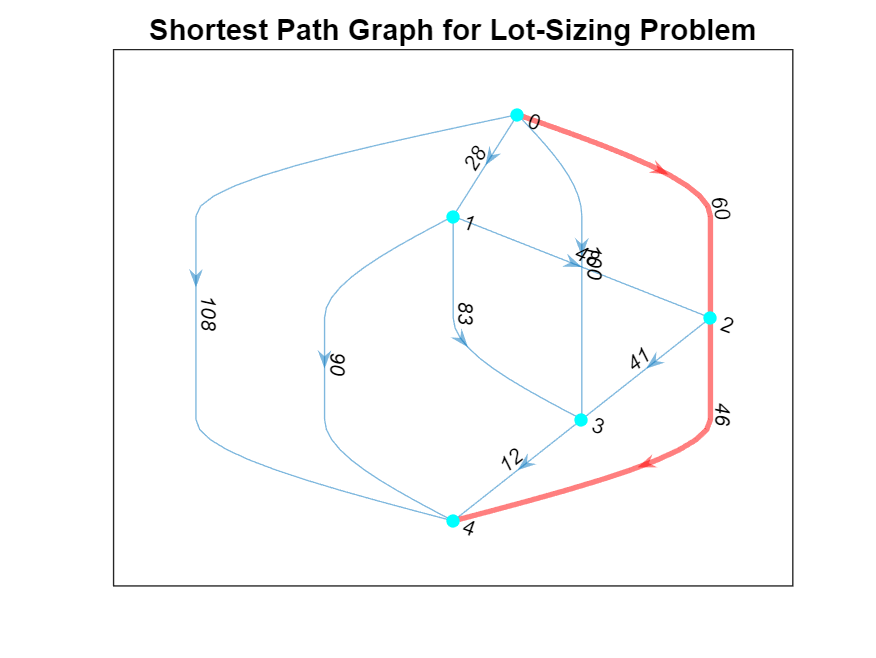


% Plot the graph
figure;
p = plot(G, 'EdgeLabel', G.Edges.Weight, 'Layout', 'layered', 'NodeColor', 'cyan', 'NodeLabel', 0:n);
title('Shortest Path Graph for Lot-Sizing Problem');
highlight(p, shortest_path, 'EdgeColor', 'r', 'LineWidth', 2);